**Dear Students, **

**This is an optional exercise for the theory part of the course. **

**In this excercise, we will go through DFT and IDFT and their use in computing the convolutions. **

# **Slow and Fast Convolutions  **

## **Learning Outcome**: 

At the end of this exercise, you will be able to implement the convolution operation to compute the output of a system given an input sequence and the impulse response of the system, using two different techniques. The technique we will explore are:

- Direct or Slow Convolution

- Fast Convolution 

## Background:

In the theory part, you studied about 4 ways of representing a linear time-invariant  (LTI) system [1, 4]. They are

- Impulse response, denoted by $h[n]$

- Frequency response, denoted by $H(e^{j\omega})$

- System function (Z-transform), denoted by $H(z
)$

- Linear Constant Coefficient Difference Equation, which is $y[n] = - \sum_{k=1}^Na_k y[n-k] + \sum_{k=0}^M b_kx[n-k]$. 

Each one of the above representations play a vital role in design and/or implementation of digital systems (such as filters). 

In this lab, we will talk about implementation of a system with finite impulse response (FIR) by convolving the input sequence with the impulse response of the system. 

## Direct or Slow Convolution:

In an FIR filter, we have, $h[n]\geq 0, \text{for}\; N_1\leq n \leq N_2
$ and $h[n] = 0
$ otherwise. For simplicity, let us assume, $N_1 = 0
$ and $N_2 = L_h-1
$. Such a filter is called as an $L_h$-length FIR filter. Now, given an input sequence, $x[n]$, of length $L_x$ (what does it mean?),  we can compute the output sequence by the following convolution sum:  

                                                          $y[n] =  \sum_{k=0}^{L_h-1}h[k]x[n-k]$ for $n\in \mathbb{Z}$  

It is interesting to note that the above convolution sum has the form of the following LCCDE, $y[n] =  \sum_{k=0}^{L_h-1}b_kx[n-k]$, where $b_k = h[k]$ for $k=0,\ldots, L_h-1$. The above approach of computing convolution by direct evaluation of the convolution sum is called the Direct or Slow Convolution. The reason why it is called as the "Slow" convolution will be clear at the end of the notebook.

Let us write some code to implement this convolution.

### **Coding Question 1 (10 Points): **

- Generate the impulse response, $h[n]$, of a causal moving average filter of an arbitrary length, $L_h$. 

% Write your code here
Lh = 10

Lh = 10

h_n = 1/Lh*ones(Lh,1);

- Generate a discrete-time sequence, $x[n]$ of an arbitrary length, $L_x$. 

% Write your code here
x_n = [1,2,3,4,5];
L = size(x_n);
Lx = L(2);

- Compute $y[n] = h[n]\ast x[n]$by evaluating the convolution sum. 

% Write your code here
y_n = zeros(Lx+Lh-1,1);
for i = 1:Lx
      for j = 1:Lh
       y_n(i+j-1) = y_n(i+j-1) + h_n(j)*x_n(i);
      end
end
y_n;

- Verify your answer using the inbuilt Matlab function, [conv](https://in.mathworks.com/help/matlab/ref/conv.html). 

% Write your code here
y = conv(x_n,h_n);

### **Inference 1 (10 Points): **

- What is the maximum length of $y[n]$ over which it can be non-zero? Express your answer in terms of $L_h~\text{and} ~L_x$.

            ANSWER:The maximum length over which it can be nonzero is Lx+Lh-1.

- In order to compute $y[n_0]$, how many and which all samples of the input sequence $\{x[n]\}$ are required? What is the buffer memory requirement to store them? 

            ANSWER:Case1 n0>=min(Lx,Lh)

                                                n0 number of elements required.

                             Case2 min(Lx.Lh)<n0<=max(Lx,Lh)

                                                min(Lx,Lh) samples required.

                              Case3 max(Lx,Lh)<n0<=Lx+Lh-1

                                                Lx+Lh-n0 samples required

        Remember i have taken indices from 1,2,...,N as we take in MATLAB instead of 0,1,2,...N.

- Which kind of buffer would you use for the above convolution operation? (Hint: [https://en.wikipedia.org/wiki/Circular_buffer,](https://en.wikipedia.org/wiki/Circular_buffer,) [https://www.dspguide.com/ch28/2.htm](https://www.dspguide.com/ch28/2.htm))

            ANSWER:

## **Fast Convolution: **

Noting that discrete-time Fourier transform (DTFT) of $h[n]\ast x[n]$ is equal to $H(e^{j\omega})X(e^{j\omega})$, where $H(e^{j\omega}) = \text{DTFT}(h[n])$and $X(e^{j\omega}) = \text{DTFT}(X[n])$, we can consider the following approach for computing the convolution sum to obtain $y[n]$:

- Compute $H(e^{j\omega})$ and $X(e^{j\omega})$

- Obtain $Y(e^{j\omega})  =  H(e^{j\omega})X(e^{j\omega})$

- Compute the inverse DTFT of $Y(e^{j\omega})
$ to obtain $y[n]$. 

If we are able to do the above operations more efficiently than the direct computation of the convolution sum, we could adopt this approach. We will explore this in the below. 

Let us code a bit. 

### **Coding Question 2 (10 Points):**

- Compute and plot the DTFT of $h[n]$ you generated above, over $0\leq \omega <2\pi$.  

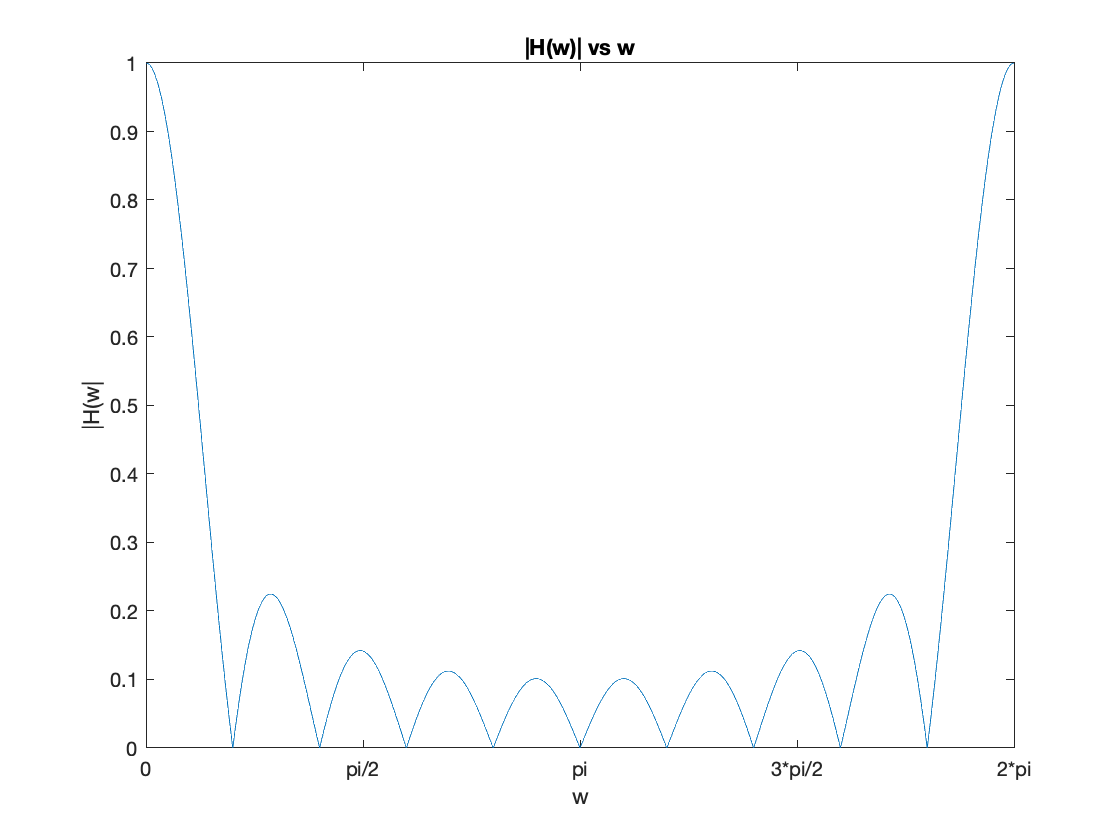

% WRITE YOUR CODE HERE. 
N = 1000;
omega = 0:pi/N:2*pi;
Hw = zeros(length(omega),1);
for i=1:length(omega)
    for j=1:Lh
        Hw(i) = Hw(i) + h_n(j)*exp(-omega(i)*1j*(j-1));
    end
end
Hw_mag = abs(Hw);
plot(omega,Hw_mag)
title("|H(w)| vs w")
xlim([0,2*pi])
set(gca,'XTick',0:pi/2:2*pi)
set(gca,'XTickLabel',{'0','pi/2','pi','3*pi/2','2*pi'})
xlabel("w")
ylabel("|H(w|")

### **Coding Question 3 (10 Points):**

- Write a code snipped to reconstruct $h[n]$ from the DTFT you have computed

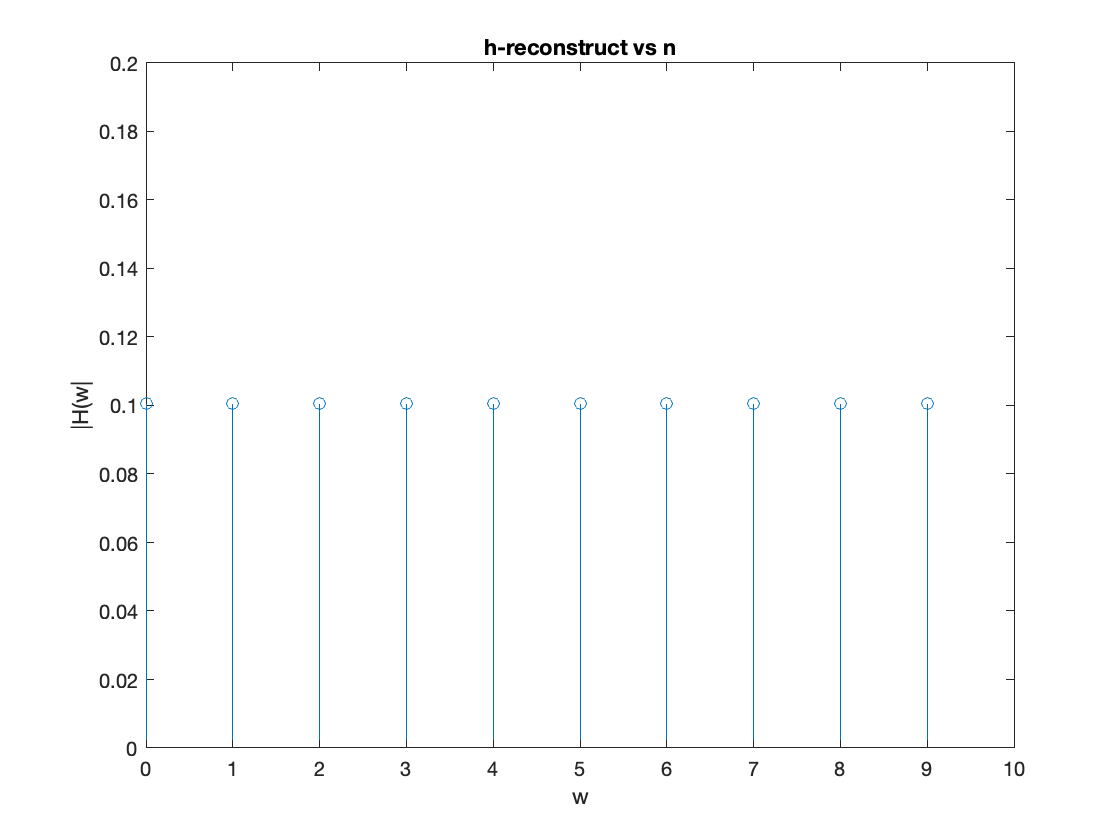

% WRITE YOUR CODE HERE. 
h_reconstruct = zeros(Lh,1);

for i=1:Lh
    for j=1:length(omega)
        h_reconstruct(i) = h_reconstruct(i) + Hw(j)*exp(1j*omega(j)*(i-1));
    end
    h_reconstruct(i) = 1/length(omega)*h_reconstruct(i);
end
h_reconstruct;
stem(0:Lh-1 ,abs(h_reconstruct))
title("h-reconstruct vs n")
ylim([0,0.2])
xlim([0,10])
xlabel("w")
ylabel("|H(w|")

### Inference 2 **(10 Points):**

- Were you able to reconstruct $h[n]$ from $H(e^{j\omega})$? Why? Why not? 

            ANSWER:No,we cannot reconstruct h[n] back from H(w).

                             In a digital computer we cannot perform infinite summation or integration so here we had to take IDFT at N samples(here N=1000) because digital computers work on discretized values and hence the h[n] we get is approximation at number of samples taken.

- Which parameters in your code affect the reconstructability? 

            ANSWER:The parameters that affected the reconstructability was N that is the number of samples we take to construct DTFT of the signal.

As you might have noted, one of the main challenges with adopting the above approach is that computing the DTFT in a digital computer is not possible as $\omega
$ is a continuous variable representing the digital frequency.  One way to deal this problem is by using the approach you have just used!  That is, by computing DTFT values at closely (usually uniformly) spaced sample values of $\omega
$, i.e., at $-\pi, -\pi+\delta\omega, \pi+2\delta\omega, \ldots, \pi-\delta\omega, \pi$ or at $0,  \delta\omega, 2\delta\omega, \ldots, 2\pi-\delta\omega, 2\pi$ (Recall that it is sufficient to compute the DTFT function only over a period of length$2\pi$.)  However, we should be careful with this approach in that, we should select $\delta \omega$ such that we are able to reconstruct $x[n] $from the sampled DTFT.  Let us assume that $\delta \omega =  \frac{2\pi}{N}$, where, we need to select $N$ such that we are able to recover/reconstruct inverse DTFT values without loss of information [2]. We will find such an $N$in the following. 

Assume a discrete-time sequence $x[n], -\infty<n<\infty$ and consider its DTFT  $X(e^{j\omega})$ at $\omega = \frac{2\pi}{N}k, \;\; k = 0,\ldots, N-1.$We have, 

                                                             $X\left(\frac{2\pi k}{N}\right) = \sum_{n=-\infty}^{\infty}x[n]e^{-j2\pi k n/N}},  k=1,\ldots, N-1.$ for $k=0,\ldots, N-1$.

Noting that $e^{-j2\pi k(n+mN)/N} = e^{-j2\pi kn/N} $for any integer $m$, we can re-arrange the above equation as follows:

                              
$$X\left(\frac{2\pi k}{N}\right) =\ldots+\sum_{n=-N}^{-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}
$$
  
$$+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}
$$
  
$$\sum_{n=N}^{2N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}+\ldots
$$
 
$$+\ldots
$$
  
$$=\sum_{l=-\infty}^{\infty} \sum_{n=l N}^{l N+N-1} x[n]e^{-j2\pi k n/N}}+\sum_{n=0}^{N-1}x[n]e^{-j2\pi k n/N}}
$$


    Changing the index in the inner summation from $n $ to $n-lN$ and changing the order of the summation, we have, 

                                                                 $X\left(\frac{2\pi k}{N}\right) =\sum_{n=0}^{N-1}   \left[\sum_{l=-\infty}^{\infty} x[n-l N] \right]e^{-j2\pi k n/N}}$ for $k=0,\ldots, N-1.$

Let $x_{p} [n] = \sum_{l=-\infty}^{\infty} x[n-l N]$for $n\in \mathbb{Z}$. 

Let us write a quick code snippet to visualize $x_p[n]$. Let $x[0] = 0, x[1] =0.25, x[2] =0.5, x[4]=0.75, x[5]=1$and $x[n]=0$ for all other values of $n$. 

### **Coding Question 4 (5 Points):**

Write a code to generate and plot $x_p[n]$ for an arbitrary value of $N.$

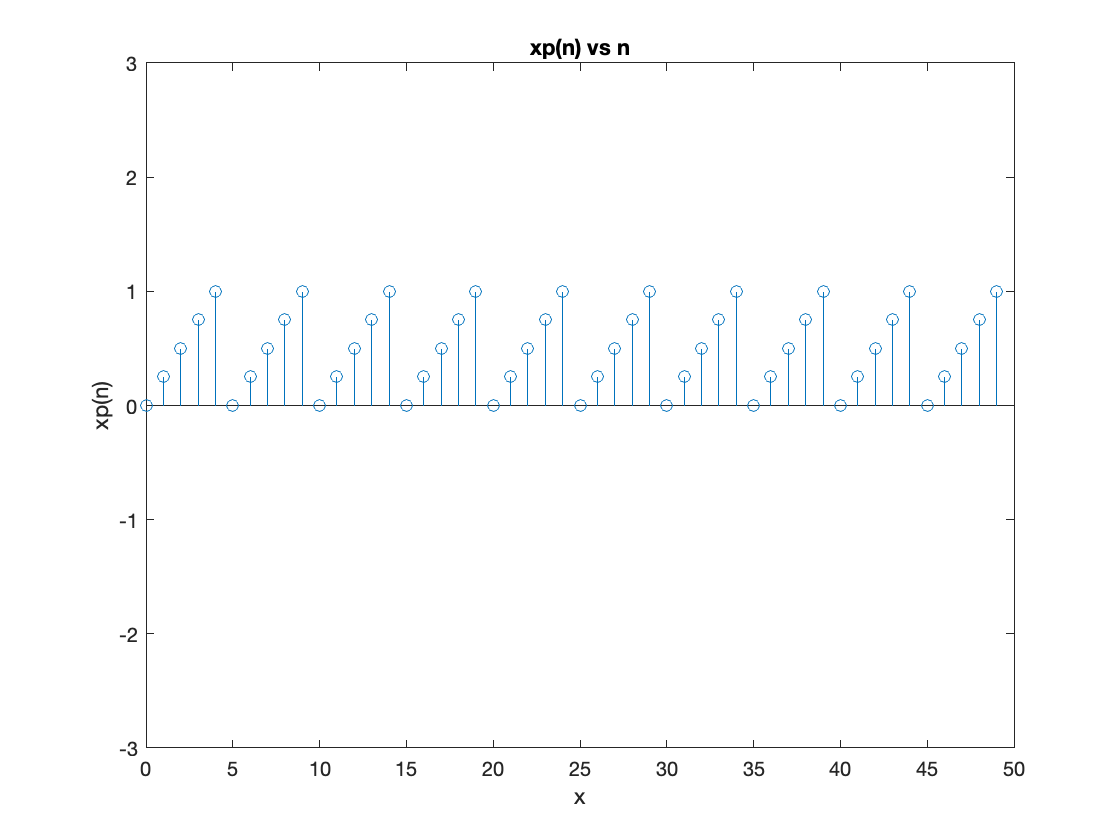

N = [5];   % Assume a value of N
x = [0, 0.25, 0.5 0.75 1]; % given sequence
x_p = [];  % CONSTRUCT THIS
% WRITE A CODE SNIPPET TO PLOT x_p[n]
num = N*10;
tmp = zeros(N,1);
if(N >= length(x))
    for i=1:N
        if(i>length(x))
            tmp(i) = 0;
        else
            tmp(i) = x(i);
        end
    end
else
    for j=1:length(x)
        tmp(mod(j-1,N)+1) = tmp(mod(j-1,N)+1)+x(j);
    end
end
tmp;
for i=1:num
    for j=1:1000
        x_p(i) = tmp(mod(i-1-(j-1)*N,N)+1);
    end
end
x_p;
stem(0:num-1,x_p)
title("xp(n) vs n")
ylim([-3,3])
xlabel("x")
ylabel("xp(n)")
hold off

### **Inference 3 (5 Points):**

- Is $x_p[n]$ is a periodic signal? If yes, what is its fundamental period?  

            ANSWER:Yes,x_p(n) is a periodic signal and its fundamental period is N,otherwise if x is periodic itself for instance [1,2,1,2] and we take N-pt DFT then period will be 2 which is period of sequence itself.

- What should be the relationship between $L_x$ and $N$to be able to get back $x[n]$ from $x_p[n]$?

            ANSWER:The relationship between Lx and N is-

                            N >= Lx

You might have got them right! $x_p[n]$is a periodic sequence with period $N$. Hence, you can express it using Fourier series as follows: 

                                                      $x_p[n] = \sum_{k=0}^{N-1}c_k e^{j2\pi k n/N}$ for $n = 0, \ldots, N-1$, 

where $c_k = \frac{1}{N}\sum_{n=0}^{N-1}x_p[n]e^{-j2\pi kn/N}$ for $k=0,\ldots, N-1$. Note that $c_k=\frac{1}{N}X\left(\frac{2\pi k }{N}\right) $ for $k=0,\ldots, N-1. $

This implies that 

$x_p[n] = \frac{1}{N}\sum_{k=0}^{N-1}X\left(\frac{2\pi k}{N}\right)e^{j2\pi k n/N}$ for $n = 0,\ldots, N-1$. 

The above equation helps in reconstruction of the periodic $x_p[n]$ from the samples of $X(e^{j\omega})$taken at $w = 2\pi k/N$. However, we want to get $x[n]$, not $x_p[n]$!

### **Theory Question 1 (0 Points):**

How and when can we get back $x[n]$ from $X\left(\frac{2\pi k}{N}\right)$values at $k=0,\ldots, N-1$? (Hint: use your Inference 3). 

Note that we can recover, $x[n]$ from $x_p[n]$ when $N \geq L_x$, i.e., when there is no *time-domain aliasing. * In other words, the smallest value of $N$required to get back $x[n]$ is $L_x$. 

The above sampled $X(e^{j 2 \pi k/N})$is called as the $N$-point DFT and denoted simply by $X[k]$. 

Hence, we have the following DFT and IDFT pair for a sequence $x[n]$ with $N \geq L_x$. 

                                                $N$**-point DFT:   **$X[k] = \sum_{n=0}^{N-1}x[n]e^{-j2\pi kn/N}$for $k=0,\ldots, N-1$

                                                $N$**-point IDFT:  **$ x[n] = \frac{1}{N}\sum_{k=0}^{N-1}X[k]e^{j2\pi k n/N}$for $n = 0,\ldots, N-1$. 

Let us now implement the following now. 

### **Coding Question 4 (10 Points):**

- Compute and plot $4$-point DFT and $100-$point DFT of the sequence, $x[n] = [1, 1, 1, 1]$. Plot them in the same figure. You need to think about how you will compute $100
$-point DFT of a sequence of length $4$(Hint: use zero-padding for the last 96 positions to generate a $100
$-point sequence from $x[n]$)

- Compare your answer with the Matlab inbuilt function, fft

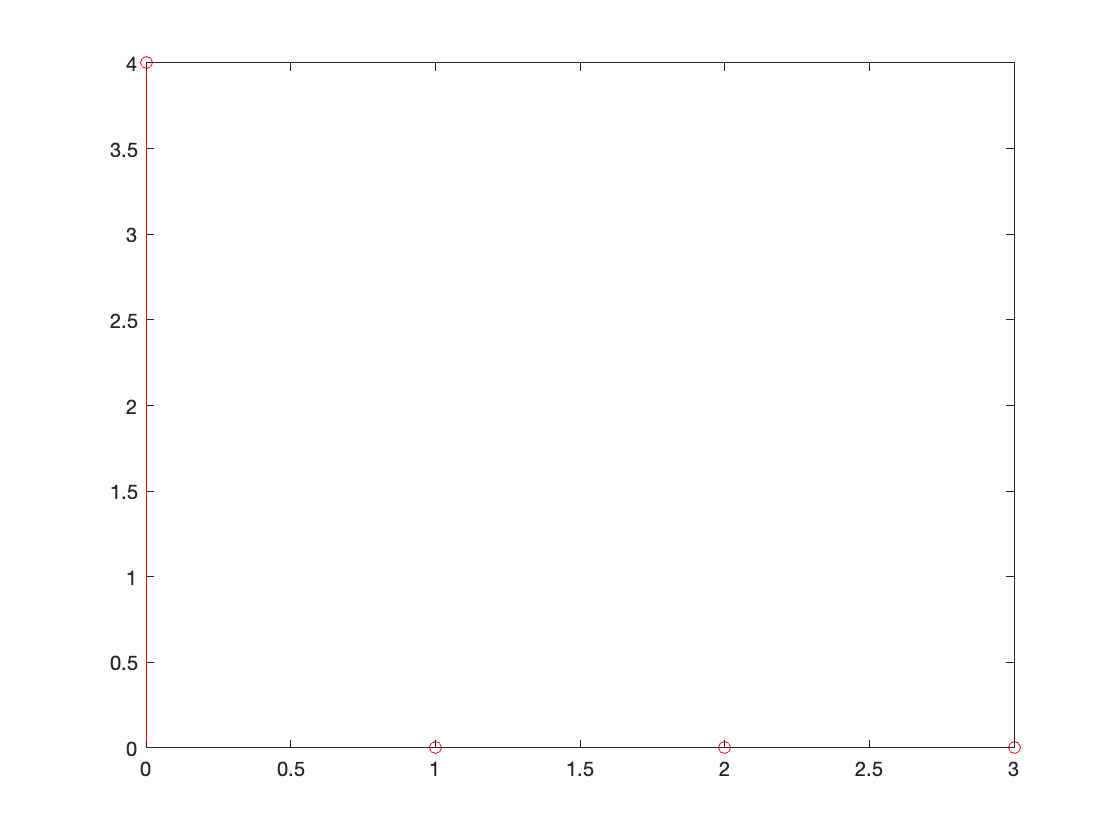

 % Write your code here. 
 x_n = [1,1,1,1];
 L = length(x_n);
 N1 = 4;
Hw = zeros(N1,1);
for i=1:N1
    for j=1:L
        Hw(i) = Hw(i) + x_n(j)*exp(-2*pi*1j*(j-1)*(i-1)/N1);
    end
end
 N2 = 100;
Hw1 = zeros(N2,1);
for i=1:N2
    for j=1:L
        Hw1(i) = Hw1(i) + x_n(j)*exp(-2*pi*1j*(j-1)*(i-1)/N2);
    end
end
Hw_mag = abs(Hw);
Hw_mag1 = abs(Hw1);
stem(0:N1-1,Hw_mag,'color',[1,0,0])

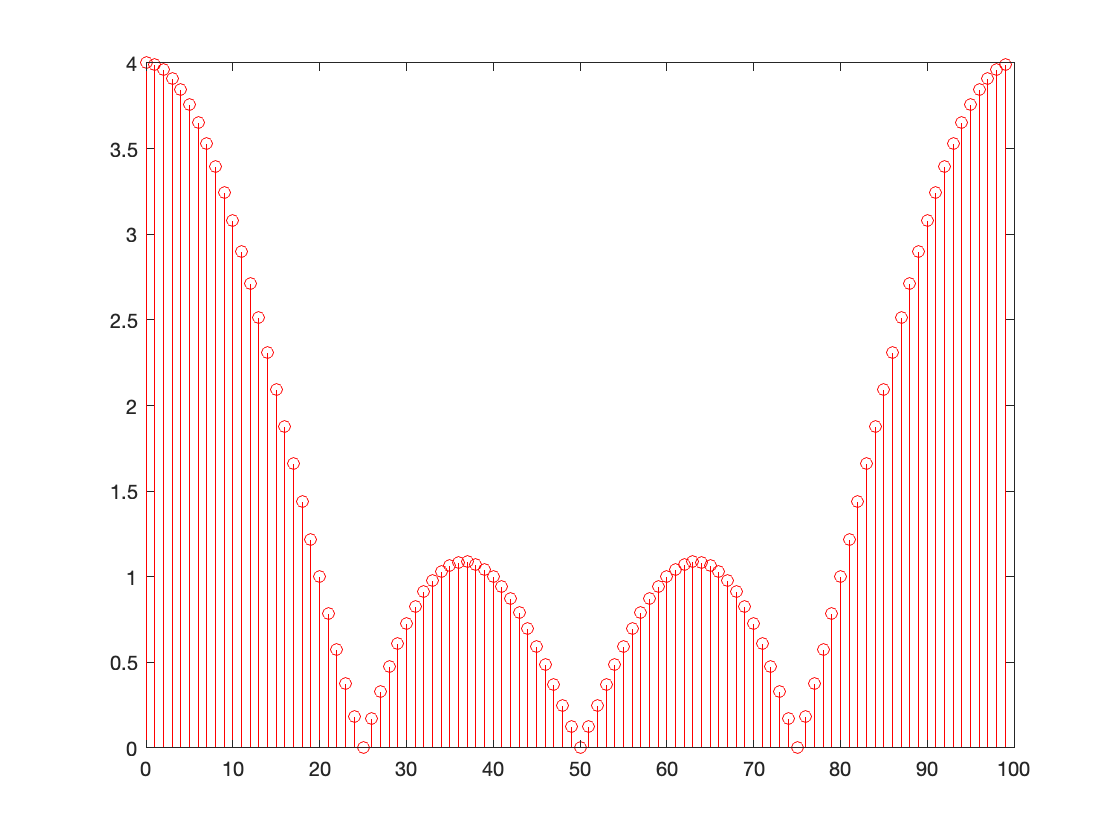

stem(0:N2-1,Hw_mag1,'color',[1,0,0])

stem(0:N1-1,abs(fft(x_n,4)),'color',[1,0,0])

stem(0:N2-1,abs(fft(x_n,100)),'color',[1,0,0])

- Now, plot the DTFT of $x[n]$ for $\omega\in [-\pi, \pi]$, based on your DFT coefficients. (see [fftshift](https://in.mathworks.com/help/matlab/ref/fftshift.html))

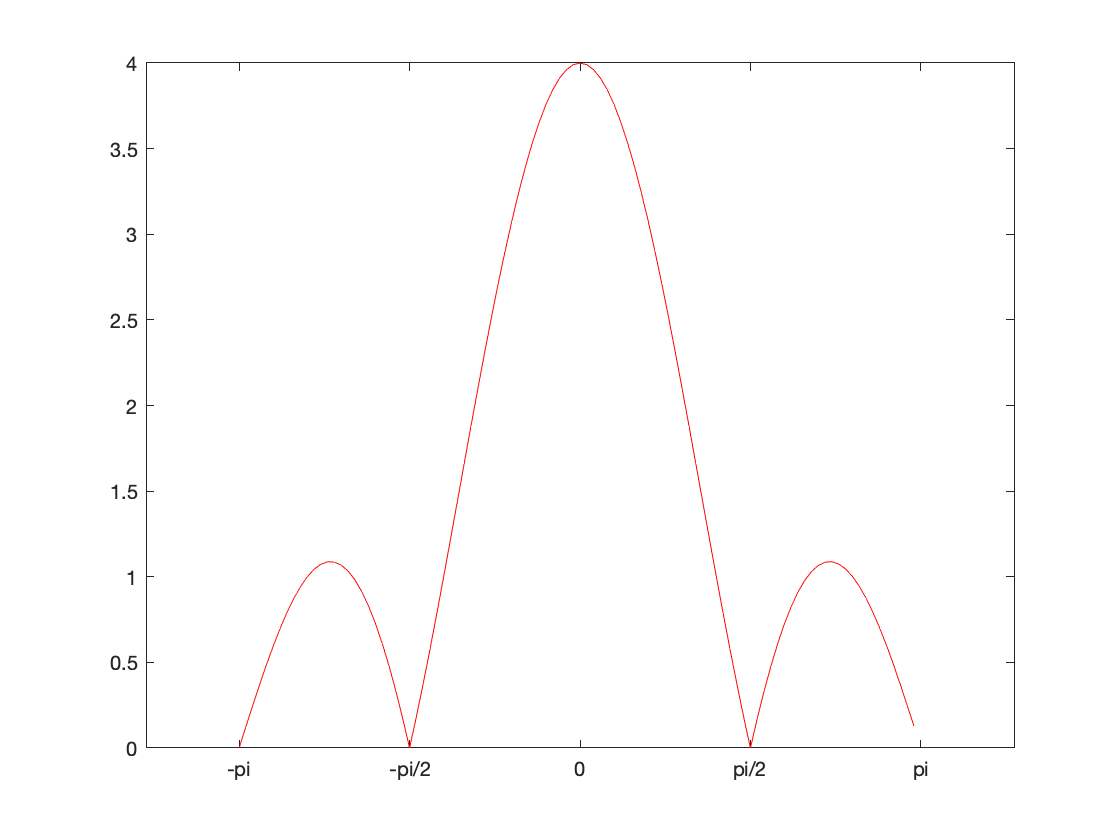

 % Write your code here. 
Y = fftshift(Hw_mag1);
plot(-pi:2*pi/length(Hw_mag1):pi-2*pi/length(Hw_mag1),abs(Y),'color',[1,0,0])
set(gca,'XTick',-pi:pi/2:pi)
set(gca,'XTickLabel',{'-pi','-pi/2','0','pi/2','pi'})

### Inference 4 **(10 Points):**

- What are your observations? 

ANSWER:I observe that DFT calculated from library funciton fft and self implemented code matches.As,N>=Lx so we can uniquely recover the signal back from the DFT coefficients.Also using fftshift we found out that it centers zero frequency component to the center of obtained array.

Recall that we wanted to obtain the sequence $y[n]$. We have developed a way to compute a Fourier Transform and its inverse, namely DFT and IDFT of a discrete sequence in a digital computer. Now, can we compute DFTs of $h[n]$ and $x[n]$ to obtain $H[k]$ and $X[k]$, respectively, multiply them and take the IDFT of the result to get $y[n]? $

For answering the above question, recall the following from your Signals and Systems class:

Assume that  $H[k]$ and $X[k]$ are $M$-point DFT of $h[n]$ and $x[n]$, respectively. Then, 

                                                                  $\tilde{y}[n] = M\text{-Point IDFT}(X[k]H[k]) = \sum_{k=0}^{M-1}h[k][x[(n-k)_M]$, for $n = 0,\ldots, M-1$

where $(n-k)_M$ is the modulo $M$value of $(n-k)$which will take a value in $\{0,1, \ldots, M-1\}$. 

The above operation is called the circular *convolution *and it is usually denoted by $\otimes$, i.e., the $M$-point circular convolution of  $h[n]$ and $x[n]$,  $h[n]\otimes x[n] = \sum_{k=0}^{M-1}h[k][x[(n-k)_M]$. 

### Coding Question 5 **(10 Points):**

- Generate $h[n]$ and $x[n]$ of lengths $L_h$ and $L_x$, respectively. 

- Compute $M$-point circular convolution of them. 

- Compute $H[k]$ and $X[k]$,  $M$-point DFTs of $h[n]$ and $x[n]$, respectively for an arbitrary value of $M$. 

- Multiply them to obtain $\tilde{Y}[k]$ and compute its $M$-point IDFT to obtain $\tilde{y}[n]$. 

- Compare your answer with the directly computed convolution above and also by using the  inbuilt Matlab function, [ccnv](https://in.mathworks.com/help/signal/ref/cconv.html). 

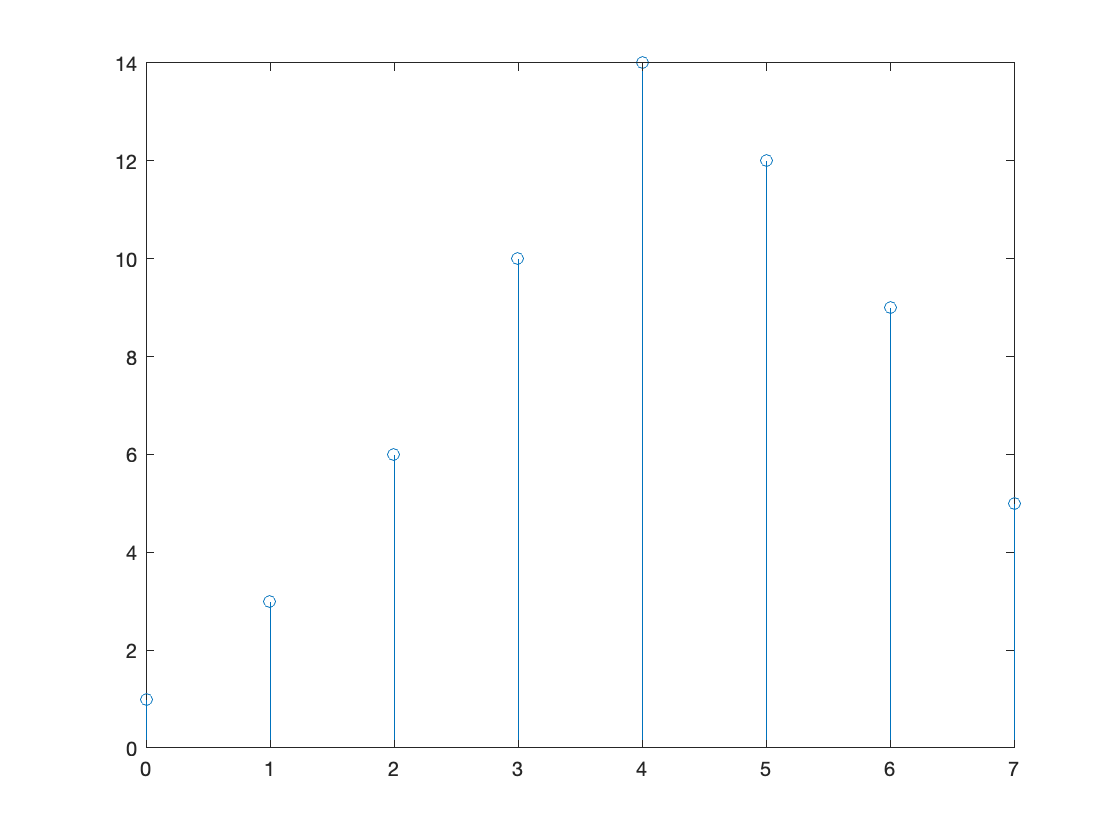

% Write your code here. 
h_n = [1;1;1;1];
x_n = [1;2;3;4;5];
M = length(h_n)+length(x_n)-1;
y_n = zeros(M,1);
h_n = [h_n;zeros(M-length(h_n),1)];
x_n = [x_n;zeros(M-length(x_n),1)];
for i=1:M
    for j=1:M
        y_n(i) = y_n(i) + h_n(j)*x_n(mod(i-j,M)+1);
    end
end
stem(0:M-1,y_n)

H_k = fft(h_n,M);
X_k = fft(x_n,M);
Y_k = H_k.*X_k;

stem(0:M-1,cconv(x_n,h_n,M))

y_n1 = ifft(Y_k,M);
stem(0:M-1,y_n1)

### **Inference (10 Points):**

- For what values of $M$, are $y[n]$ and $\tilde{y}[n]$ will be the same? 

            ANSWER:Both will be same when M>=Lx+Lh-1.

Under the above condition on $M$, we can obtain the output $y[n]$using the above technique. Such a technique of obtaining the convolution sum of two finite-length sequences, using the DFT and IDFT operations is called as the *fast convolution. *You may be wondering why it would be fast, as it seems to involve more number of steps than with the *direct convolution * used earlier. However, it turns out that when the DFT and IDFT are computed using any of a large class of algorithms called Fast Fourier Transforms (FFT), fast convolution is more efficient (faster) than the direct convolution.  Hence, the fast convolution is a very important signal processing tool [3]. Can you think of some advantages of direct convolution over the fast convolution? 

# Practical Experiment (50 Points) 

Now, record your voice or some music for $5
$ seconds to obtain $x[n]$ and filter it using the low-pass filter of length M (which you should choose):   

- Speak and record your voice or music for 5 seconds (see [audiorecorder](https://in.mathworks.com/help/matlab/ref/audiorecorder.html) and[ https://in.mathworks.com/matlabcentral/answers/357862-real-time-recording-audio-filtering](https://in.mathworks.com/matlabcentral/answers/357862-real-time-recording-audio-filtering))

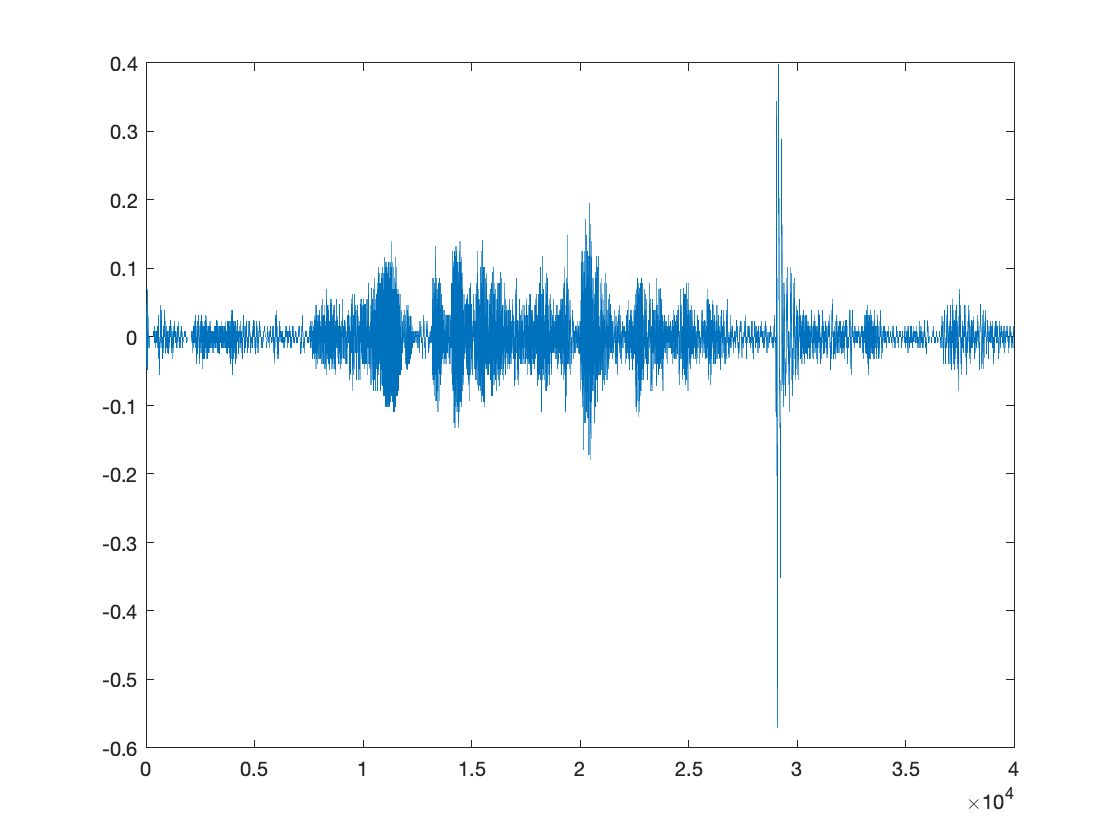


x =  [];    % Write a code snippet to record your voice or some music for 5 seconds and store it in x as an one-dimensional vectors
recorder = audiorecorder;
recordblocking(recorder,5);
x = getaudiodata(recorder);
plot(x)

- Now, using [fft](https://in.mathworks.com/help/matlab/ref/fft.html), roughly find the frequency components in your recorded $x$. 

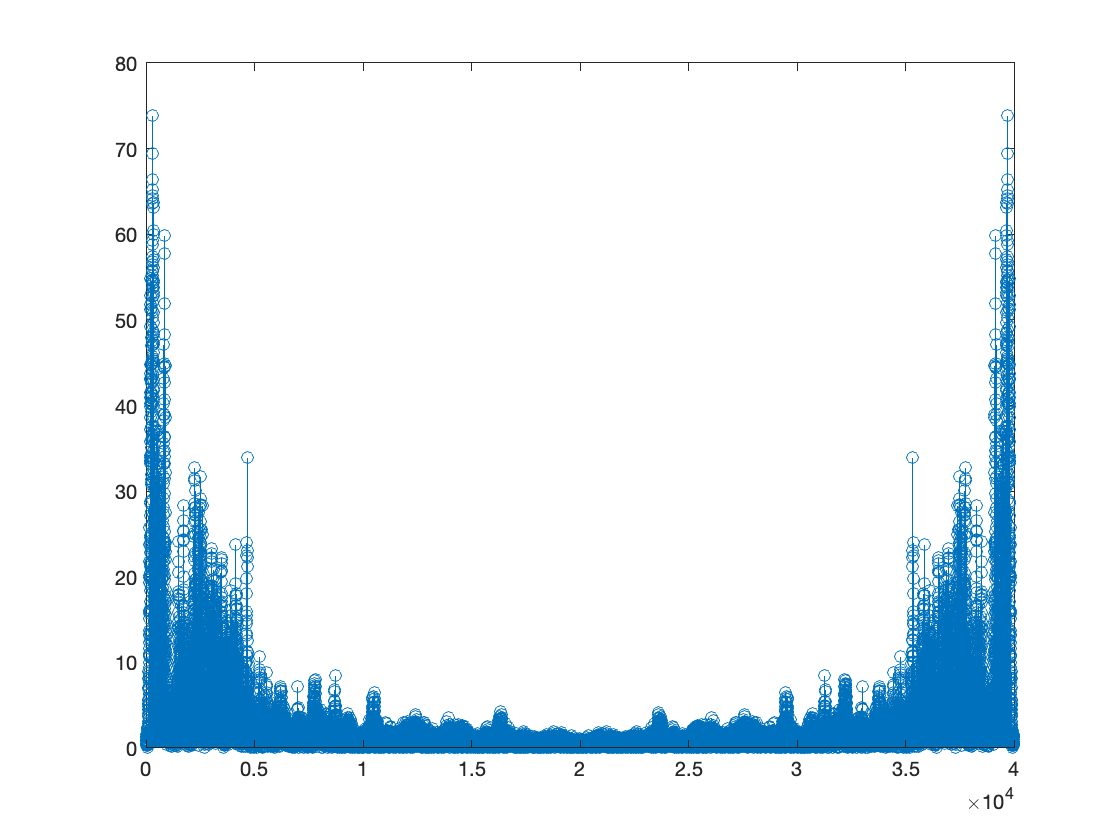

        % Write your code here
        y = fft(x);
        stem(0:length(x)-1,abs(y))

- Now, in order to remove frequencies greater than 3000 Hz components in $x[n]$, design $h[n]$, by finding appropriate $M$.

M = [40];
h  = (1/M)*ones(1,M); 



- Now filter $x[n]$using $h[n]$ and display the output as a plot and sound:

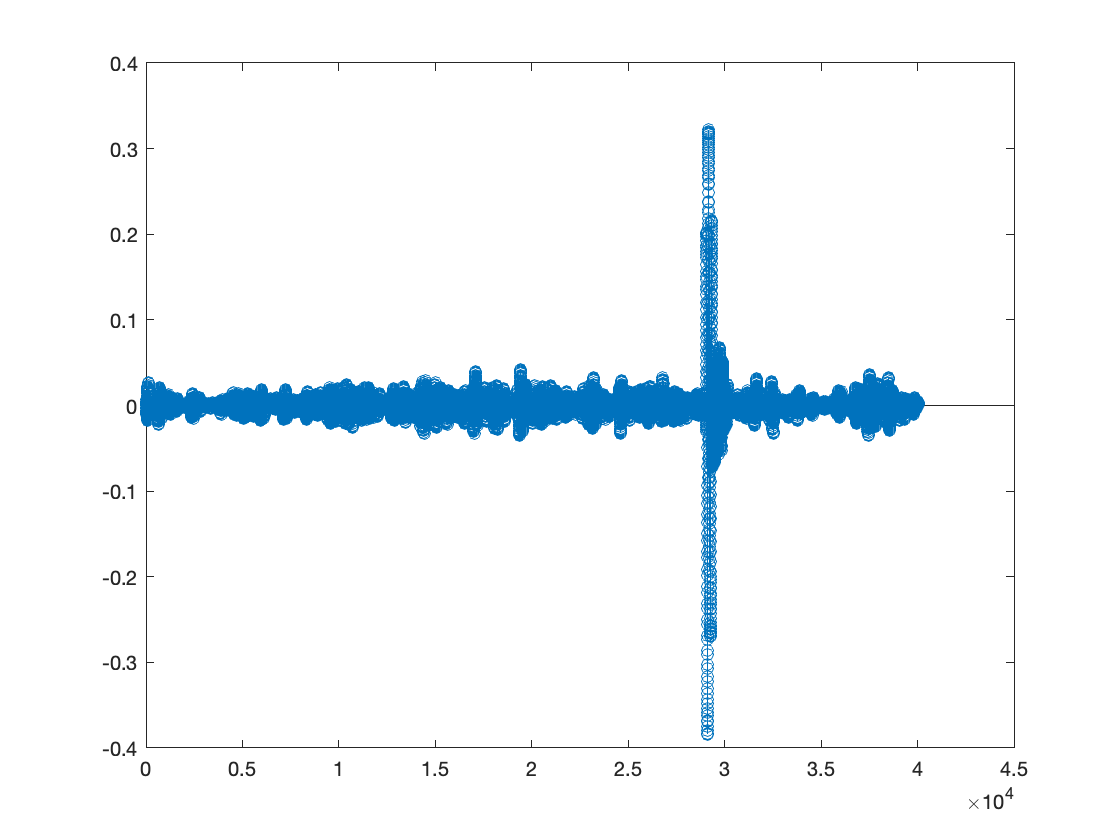

y =  [];    % Filter x using the filter with impulse response h

% Plot the output y
y = cconv(h,x);
stem(0:length(h)+length(x)-2,y)

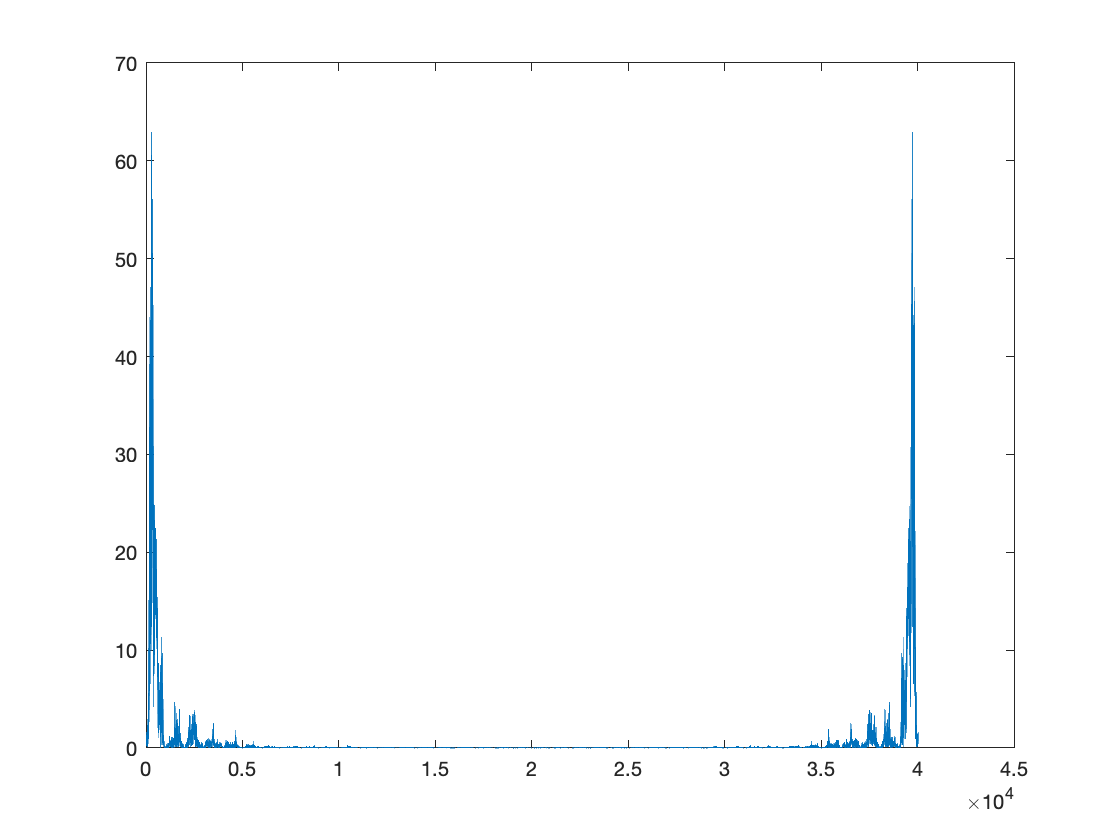

% Plot y in frequency domain
plot(abs(fft(y)))

% Output y on your speaker
sound(y)

- Make observations and write down in the below: 

            ANSWER: 

# (Optional) Convolution and Correlation:

** Note: This part of the code will accounted for your grading**

One more very important operation, similar to the convolution is correlation. Between any two sequences, $x[n]$ and $y[n]$, it is defined as follows:

                                                                           $r_{xy}[l]=\sum_{n=-\infty}^{+\infty}x[n]y[n-l]$.

**Question: **

- How are the convolution  of $x[n]$ and $y[n]$ and correlation of $x[n]$ and $y[n]$ related? 

Let us write some code: 

### Coding Question **(10 Points):**

- Generate a sequence $x[n]$

- Generate another sequence, $y[n] = 0.75x[n-D]$

- Compute the correlation between these two sequences. 

             % Write your code here. 

### Inference **(10 Points):**

- Is there any relationship between $r_{xy}[l]$ and $D$? Comment. 

            ANSWER:

- What does the correlation of two sequences signify? Think of applications where you can use the correlation operation to find out important parameters (Hint: Note that $D$ is the delay). 

             ANSWER:

## Other References

- [https://allsignalprocessing.com/](https://allsignalprocessing.com/)

- John G. Proakis and D.G. Manolakis, Digital Signal Processing: Principles, Algorithms and Applications, Prentice Hall, Fourth Edition.

- L.R. Rabiner and B. Gold, Theory and Application of Digital Signal Processing, Prentice Hall, 1992. 

- A.V. Oppenheim and R. W. Schafer, Discrete-Time Signal Processing, Prentice Hall, 3rd Edition.